load('C:\Users\bgrau\GitHub\ieeg_affect\EEE\qualtrics\data\pilot_master_long.mat')


lme1 = fitlme(master, 'img_rate~highcue_indx + Valence_mean +(highcue_indx|Pair) + (highcue_indx|subj)') %this is bad

lme1 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           3
    Random effects coefficients        310
    Covariance parameters                7

Formula:
    img_rate ~ 1 + highcue_indx + Valence_mean + (1 + highcue_indx | Pair) + (1 + highcue_indx | subj)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    68284    68354    -34132           68264   

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE          tStat     DF      pValue        Lower      Upper   
    {'(Intercept)' }        -4.9422       2.4478    -2.019    7869      0.043522    -9.7406    -0.14375
    {'highcue_indx'}         2.0889      0.20522    10.179    7869    3.4736e-24     1.6866      2.4912
    {'Valence_mean'}         1.0355     0.039912    25.944    7869    1.823e-142    0.95724     

% [feCI, reCI] = coefCI(lme1); % 95% confidence level (alpha = 0.05)
lme2 = fitlme(master, 'img_rate~highcue_indx + Valence_mean + exp_rate + (highcue_indx|Pair) + (highcue_indx|subj)')

lme2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           4
    Random effects coefficients        310
    Covariance parameters                7

Formula:
    img_rate ~ 1 + highcue_indx + Valence_mean + exp_rate + (1 + highcue_indx | Pair) + (1 + highcue_indx | subj)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    68160    68237    -34069           68138   

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE          tStat      DF      pValue        Lower       Upper  
    {'(Intercept)' }         -7.037        2.469    -2.8502    7868     0.0043806     -11.877    -2.1972
    {'highcue_indx'}         0.0337      0.27404    0.12298    7868       0.90213    -0.50349    0.57089
    {'Valence_mean'}        0.88975     0.042225     21.072    7868      6.25e-96 

lme3 = fitlme(master, 'img_rate~Valence_mean + exp_rate + (highcue_indx|Pair) + (highcue_indx|subj)')

lme3 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           3
    Random effects coefficients        310
    Covariance parameters                7

Formula:
    img_rate ~ 1 + Valence_mean + exp_rate + (1 + highcue_indx | Pair) + (1 + highcue_indx | subj)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    68158    68228    -34069           68138   

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE          tStat      DF      pValue        Lower      Upper  
    {'(Intercept)' }        -7.0485       2.4676    -2.8565    7869     0.0042952    -11.886    -2.2114
    {'Valence_mean'}         0.8887     0.041332     21.501    7869    1.0748e-99    0.80768    0.96972
    {'exp_rate'    }        0.18872     0.012402     15.218    7869    1.4567e-51    0.16441    0.21

lme4 = fitlme(master, 'img_rate~Valence_mean + Pair')

lme4 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           3
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    img_rate ~ 1 + Pair + Valence_mean

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    69198    69226    -34595           69190   

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE           tStat      DF      pValue        Lower       Upper  
    {'(Intercept)' }         -6.4133      0.70636    -9.0794    7869    1.3603e-19      -7.798    -5.0286
    {'Pair'        }        0.076764     0.023931     3.2077    7869     0.0013436    0.029852    0.12368
    {'Valence_mean'}          1.0391    0.0097794     106.26    7869             0        1.02     1.0583

Random effects covariance parameters (9

fitlme(master, 'img_rate~Valence_mean + (highcue_indx|Pair)')

ans = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           2
    Random effects coefficients         64
    Covariance parameters                4

Formula:
    img_rate ~ 1 + Valence_mean + (1 + highcue_indx | Pair)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    68745    68787    -34367           68733   

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE          tStat      DF      pValue         Lower      Upper   
    {'(Intercept)' }        -4.8567       2.3939    -2.0288    7870       0.042512    -9.5493    -0.16406
    {'Valence_mean'}         1.0359     0.039793     26.031    7870    2.2466e-143    0.95786      1.1139

Random effects covariance parameters (95% CIs):
Group: Pair (32 Levels)
    Name1                   Name2           

lme5 = fitlme(master, 'img_rate~Valence_mean + (exp_rate|subj)')

lme5 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           2
    Random effects coefficients        246
    Covariance parameters                4

Formula:
    img_rate ~ 1 + Valence_mean + (1 + exp_rate | subj)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    68398    68440    -34193           68386   

Fixed effects coefficients (95% CIs):
    Name                    Estimate      SE          tStat         DF      pValue     Lower      Upper  
    {'(Intercept)' }        -0.0032043     0.86053    -0.0037237    7870    0.99703    -1.6901     1.6837
    {'Valence_mean'}           0.94075    0.012638        74.436    7870          0    0.91597    0.96552

Random effects covariance parameters (95% CIs):
Group: subj (123 Levels)
    Name1                  Name2              

lme6 = fitlme(master, 'img_rate~Valence_mean + (exp_rate|subj)')

lme6 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           2
    Random effects coefficients        246
    Covariance parameters                4

Formula:
    img_rate ~ 1 + Valence_mean + (1 + exp_rate | subj)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    68398    68440    -34193           68386   

Fixed effects coefficients (95% CIs):
    Name                    Estimate      SE          tStat         DF      pValue     Lower      Upper  
    {'(Intercept)' }        -0.0032043     0.86053    -0.0037237    7870    0.99703    -1.6901     1.6837
    {'Valence_mean'}           0.94075    0.012638        74.436    7870          0    0.91597    0.96552

Random effects covariance parameters (95% CIs):
Group: subj (123 Levels)
    Name1                  Name2              

lme7 = fitlme(master, 'img_rate~Valence_mean')

lme7 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           2
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    img_rate ~ 1 + Valence_mean

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    69206    69227    -34600           69200   

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE           tStat      DF      pValue        Lower      Upper  
    {'(Intercept)' }        -5.1575       0.58831    -8.7665    7870    2.2311e-18    -6.3107    -4.0042
    {'Valence_mean'}         1.0393     0.0097856     106.21    7870             0     1.0202     1.0585

Random effects covariance parameters (95% CIs):
Group: Error
    Name               Estimate    Lower     Upper 
    {'Res Std'}        19.617    

lme8 = fitlme(master, 'img_rate~Valence_mean + highcue_indx')

lme8 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           3
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    img_rate ~ 1 + highcue_indx + Valence_mean

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    69118    69146    -34555           69110   

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE         tStat      DF      pValue        Lower      Upper 
    {'(Intercept)' }        -5.1567     0.58497    -8.8154    7869      1.45e-18    -6.3034     -4.01
    {'highcue_indx'}         2.0889     0.21984     9.5018    7869    2.6831e-21      1.658    2.5199
    {'Valence_mean'}         1.0393     0.00973     106.82    7869             0     1.0203    1.0584

Random effects covariance parameters (95% CIs):

lme9 = fitlme(master, 'img_rate~Valence_mean + exp_rate')

lme9 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           3
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    img_rate ~ 1 + Valence_mean + exp_rate

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    69006    69034    -34499           68998   

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE          tStat      DF      pValue        Lower      Upper  
    {'(Intercept)' }        -7.0332      0.59541    -11.812    7869    6.2565e-32    -8.2004    -5.8661
    {'Valence_mean'}        0.89091     0.014173     62.861    7869             0    0.86313    0.91869
    {'exp_rate'    }        0.18611     0.013003     14.313    7869     6.825e-46    0.16062     0.2116

Random effects covariance parameters (95% C

lme9 = fitlme(master, 'img_rate~exp_rate + (Valence_mean|highcue_indx)')

lme9 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                4

Formula:
    img_rate ~ 1 + exp_rate + (1 + Valence_mean | highcue_indx)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    69028    69070    -34508           69016   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat     DF      pValue        Lower      Upper  
    {'(Intercept)'}          41.63      0.73126     56.93    7870             0     40.197     43.064
    {'exp_rate'   }        0.18622     0.013008    14.316    7870    6.5226e-46    0.16072    0.21172

Random effects covariance parameters (95% CIs):
Group: highcue_indx (2 Levels)
    Name1                   Name2           

Does the actual mean of the image or the presented image mean do more to predict?

fitlme(master, 'img_rate~Valence_mean')

ans = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           2
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    img_rate ~ 1 + Valence_mean

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    69206    69227    -34600           69200   

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE           tStat      DF      pValue        Lower      Upper  
    {'(Intercept)' }        -5.1575       0.58831    -8.7665    7870    2.2311e-18    -6.3107    -4.0042
    {'Valence_mean'}         1.0393     0.0097856     106.21    7870             0     1.0202     1.0585

Random effects covariance parameters (95% CIs):
Group: Error
    Name               Estimate    Lower     Upper 
    {'Res Std'}        19.617     

fitlme(master, 'img_rate~cue_observed_mean')

ans = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           2
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    img_rate ~ 1 + cue_observed_mean

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    71359    71380    -35677           71353   

Fixed effects coefficients (95% CIs):
    Name                         Estimate    SE           tStat     DF      pValue        Lower      Upper  
    {'(Intercept)'      }         9.4401       0.58676    16.089    7870    2.4969e-57     8.2899      10.59
    {'cue_observed_mean'}        0.79967     0.0097712     81.84    7870             0    0.78051    0.81882

Random effects covariance parameters (95% CIs):
Group: Error
    Name               Estimate    Lower     Upper 
    {'Res Std'}  

The valence mean predicts better. What if we cross them?

fitlme(master, 'img_rate~Valence_mean + (highcue_indx|cue_observed_mean)')

ans = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           2
    Random effects coefficients        128
    Covariance parameters                4

Formula:
    img_rate ~ 1 + Valence_mean + (1 + highcue_indx | cue_observed_mean)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    68765    68806    -34376           68753   

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE          tStat      DF      pValue         Lower      Upper  
    {'(Intercept)' }        -5.0309       1.8513    -2.7175    7870      0.0065921    -8.6599    -1.4019
    {'Valence_mean'}         1.0372     0.030782     33.694    7870    1.2907e-232    0.97685     1.0975

Random effects covariance parameters (95% CIs):
Group: cue_observed_mean (64 Levels)
    Name1            

fitlme(master, 'img_rate~Valence_mean + (highcue_indx|Pair)')

ans = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           2
    Random effects coefficients         64
    Covariance parameters                4

Formula:
    img_rate ~ 1 + Valence_mean + (1 + highcue_indx | Pair)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    68745    68787    -34367           68733   

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE          tStat      DF      pValue         Lower      Upper   
    {'(Intercept)' }        -4.8567       2.3939    -2.0288    7870       0.042512    -9.5493    -0.16406
    {'Valence_mean'}         1.0359     0.039793     26.031    7870    2.2466e-143    0.95786      1.1139

Random effects covariance parameters (95% CIs):
Group: Pair (32 Levels)
    Name1                   Name2           

fitlme(master, 'img_rate~Valence_mean + Pair')

ans = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           3
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    img_rate ~ 1 + Pair + Valence_mean

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    69198    69226    -34595           69190   

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE           tStat      DF      pValue        Lower       Upper  
    {'(Intercept)' }         -6.4133      0.70636    -9.0794    7869    1.3603e-19      -7.798    -5.0286
    {'Pair'        }        0.076764     0.023931     3.2077    7869     0.0013436    0.029852    0.12368
    {'Valence_mean'}          1.0391    0.0097794     106.26    7869             0        1.02     1.0583

Random effects covariance parameters (95

QualtricsValenceRatings = fitlme(master, 'img_rate~Valence_mean + exp_rate + (highcue_indx|Pair) + (exp_rate|subj)')

QualtricsValenceRatings = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           3
    Random effects coefficients        310
    Covariance parameters                7

Formula:
    img_rate ~ 1 + Valence_mean + exp_rate + (1 + highcue_indx | Pair) + (1 + exp_rate | subj)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    67841    67911    -33911           67821   

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE          tStat      DF      pValue         Lower      Upper  
    {'(Intercept)' }        -5.7579       2.6253    -2.1932    7869        0.02832    -10.904    -0.6116
    {'Valence_mean'}        0.90326     0.041102     21.976    7869    6.2035e-104    0.82269    0.98383
    {'exp_rate'    }        0.14959     0.021834     6.8512    7869     7.8774e-12


lme5 = fitlme(master, 'img_rate~Valence_mean + cue_observed_mean + (highcue_indx|Pair) + (exp_rate|subj)')

lme5 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           3
    Random effects coefficients        310
    Covariance parameters                7

Formula:
    img_rate ~ 1 + cue_observed_mean + Valence_mean + (1 + highcue_indx | Pair) + (1 + exp_rate | subj)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    67865    67934    -33922           67845   

Fixed effects coefficients (95% CIs):
    Name                         Estimate    SE          tStat       DF      pValue        Lower       Upper  
    {'(Intercept)'      }         -1.1834      2.5078    -0.47188    7869       0.63703     -6.0994     3.7326
    {'cue_observed_mean'}        0.073068    0.017605      4.1505    7869    3.3521e-05    0.038558    0.10758
    {'Valence_mean'     }         0.89201    0.041967      21.255    7869 


% lme2 = fitlme(master, 'img_rate~highcue_indx + Valence_mean + Half + (highcue_indx|Pair) + (highcue_indx|subj) + (Pair|subj)')

% lmes1 = fitlme(subtable, 'img_rate~highcue_indx + Valence_mean + (highcue_indx|Pair) + (highcue_indx|subj)')

cuecolor = {[1 0 0] [0 0 1]};

wh_high = master.highcue_indx > 0;
wh_low = master.highcue_indx < 0;
hi = master(wh_high, :);
lo = master(wh_low, :);
% 
% wh_high = subtable.highcue_indx > 0;
% wh_low = subtable.highcue_indx < 0;
% hi = subtable(wh_high, :);
% lo = subtable(wh_low, :);



% [ypred, ypredCI] = predict(lme1)

tblnew = table();
% Create column of -1 and 1
% Each group of 64 needs to be balanced high/low
% fullcolumn = [];
% for i = 1:(height(ypred)/64)
%     column = randi([1,2], numValues, 1);
%     while sum(column) ~= 0
%     numValues = 64;
% 
%     % Generate random integers in the range [1, 2]
%     randomIntegers = randi([1, 2], numValues, 1);
% 
%     % Map the random integers to -1 or 1
%     column = 2 * randomIntegers - 3;
% 
%     end
%     fullcolumn = [fullcolumn; column];
% end
% tblnew.highcue_indx = master.highcue_indx(randperm(numel(master.highcue_indx)));
% tblnew.Valence_mean = linspace(min(master.Valence_mean), max(master.Valence_mean), numel(master.Valence_mean))';
% tblnew.Pair = master.Pair(randperm(numel(master.Pair)));
% tblnew.subj = master.subj(randperm(numel(master.subj)));

tblnew.highcue_indx = [hi.highcue_indx; hi.highcue_indx]

tblnew = 7872×1 table
    highcue_indx
    ____________

         1      
         1      
         1      
         1      
         1      
         1      
         1      
         1      
         1      
         1      
         1      
         1      
         1      
         1      
         1      
         1      


tblnew.Valence_mean = linspace(min(hi.Valence_mean), max(hi.Valence_mean), numel(master.Valence_mean))';
% tblnew.Pair = [hi.Pair; hi.Pair]
% tblnew.subj = [hi.subj; hi.subj]
tblnew.Pair = [hi.highcue_indx; hi.highcue_indx];
tblnew.subj = [hi.highcue_indx; hi.highcue_indx];

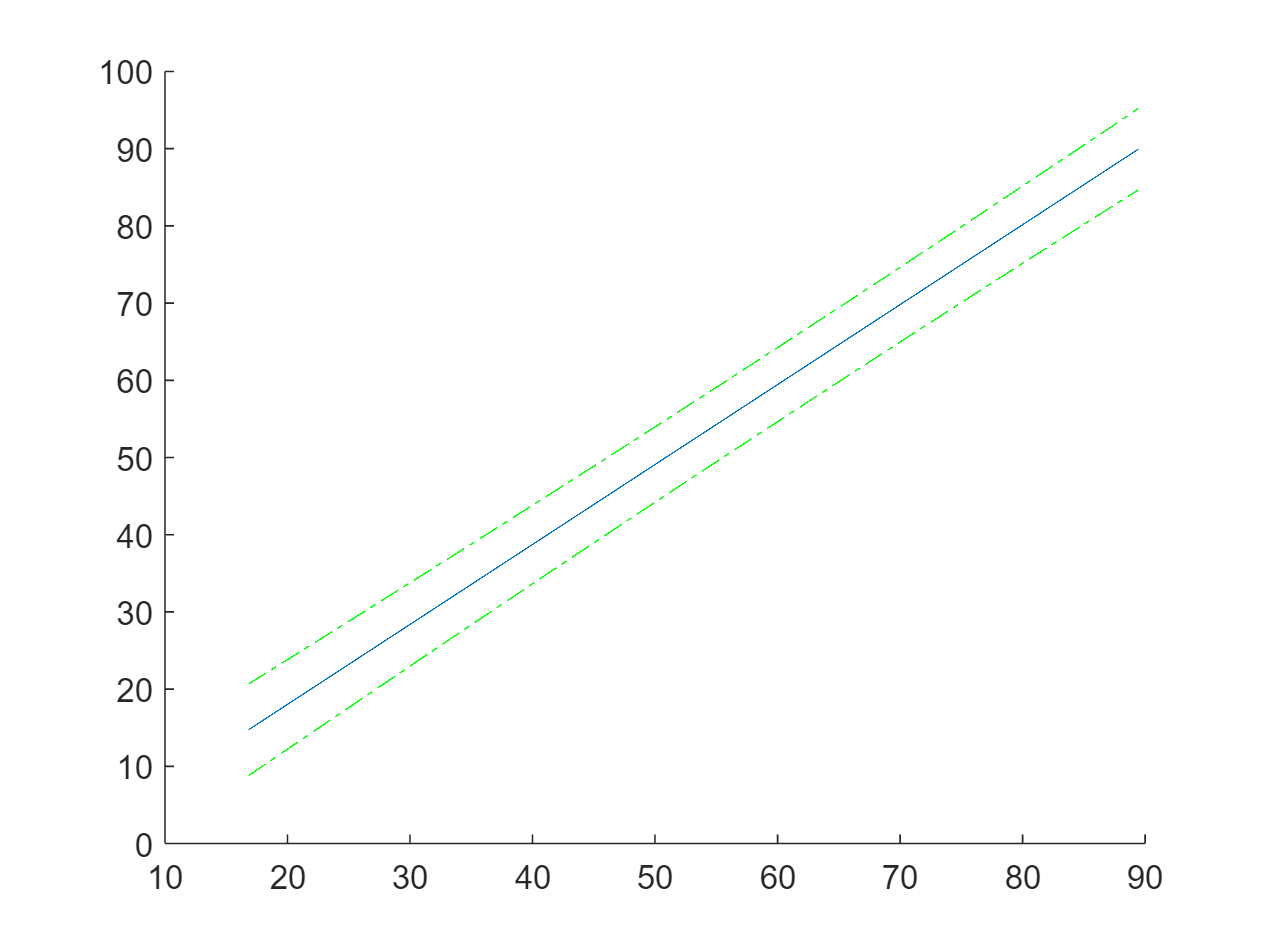

% tblnew = sortrows(tblnew, 'subj', 'ascend')

[ypred,yCI,DF] = predict(lme1,tblnew);
figure(); hold on;
h1 = line(tblnew.Valence_mean,ypred);

h2 = plot(tblnew.Valence_mean,yCI,'g-.');

% [ypred,yCI,DF] = predict(lme1,tblnew,'Simultaneous',true);
% h3 = plot(tblnew.Valence_mean,yCI,'r--');



tblnew = table();
% Create column of -1 and 1
% Each group of 64 needs to be balanced high/low
% fullcolumn = [];
% for i = 1:(height(ypred)/64)
%     column = randi([1,2], numValues, 1);
%     while sum(column) ~= 0
%     numValues = 64;
% 
%     % Generate random integers in the range [1, 2]
%     randomIntegers = randi([1, 2], numValues, 1);
% 
%     % Map the random integers to -1 or 1
%     column = 2 * randomIntegers - 3;
% 
%     end
%     fullcolumn = [fullcolumn; column];
% end
% tblnew.highcue_indx = master.highcue_indx(randperm(numel(master.highcue_indx)));
% tblnew.Valence_mean = linspace(min(master.Valence_mean), max(master.Valence_mean), numel(master.Valence_mean))';
% tblnew.Pair = master.Pair(randperm(numel(master.Pair)));
% tblnew.subj = master.subj(randperm(numel(master.subj)));

tblnew.highcue_indx = [lo.highcue_indx; lo.highcue_indx]

tblnew = 8064×1 table
    highcue_indx
    ____________

         -1     
         -1     
         -1     
         -1     
         -1     
         -1     
         -1     
         -1     
         -1     
         -1     
         -1     
         -1     
         -1     
         -1     
         -1     
         -1     


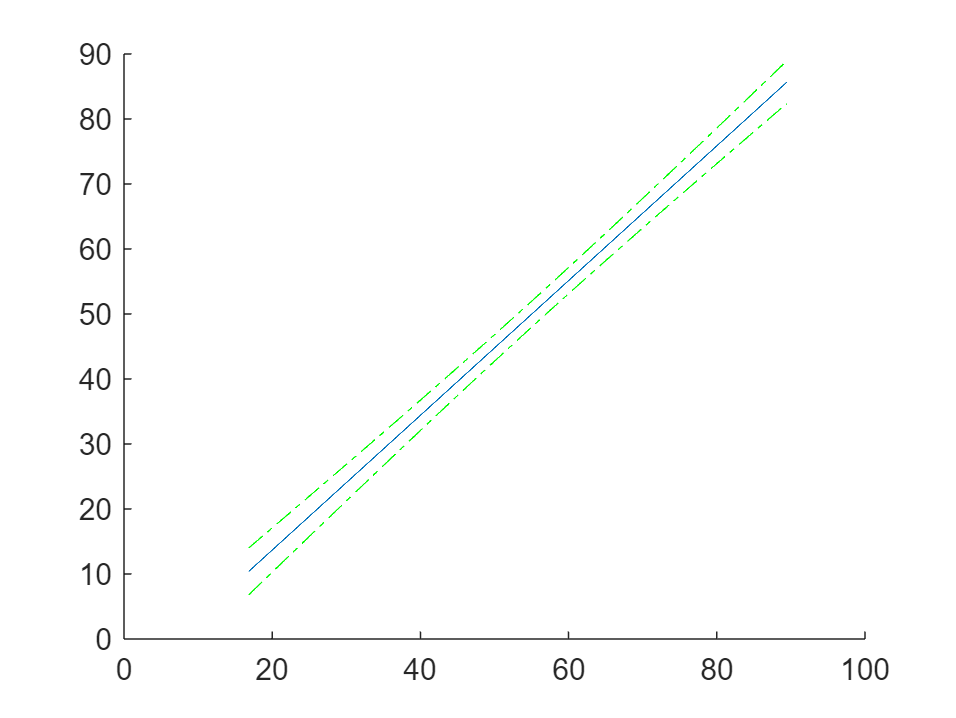

tblnew.Valence_mean = linspace(min(lo.Valence_mean), max(lo.Valence_mean), numel(master.Valence_mean))';
% tblnew.Pair = [hi.Pair; hi.Pair]
% tblnew.subj = [hi.subj; hi.subj]
tblnew.Pair = [lo.highcue_indx; lo.highcue_indx];
tblnew.subj = [lo.highcue_indx; lo.highcue_indx];

% tblnew = sortrows(tblnew, 'subj', 'ascend')

[ypred,yCI,DF] = predict(lme1,tblnew);
figure(); hold on;
h1 = line(tblnew.Valence_mean,ypred);

h2 = plot(tblnew.Valence_mean,yCI,'g-.');
% [ypred,yCI,DF] = predict(lme1,tblnew,'Simultaneous',true);
% h3 = plot(tblnew.Valence_mean,yCI,'r--');



hold off;

% lower = h{1}.line_han.YData - h{1}.errorbar_han.YNegativeDelta; % Lower bound of errors
% upper = h{1}.line_han.YData + h{1}.errorbar_han.YPositiveDelta; % Upper bound of errors
% fill([x, fliplr(x)], [lower, fliplr(upper)], rgb{2}, 'FaceAlpha', 0.3, 'EdgeColor', 'none');


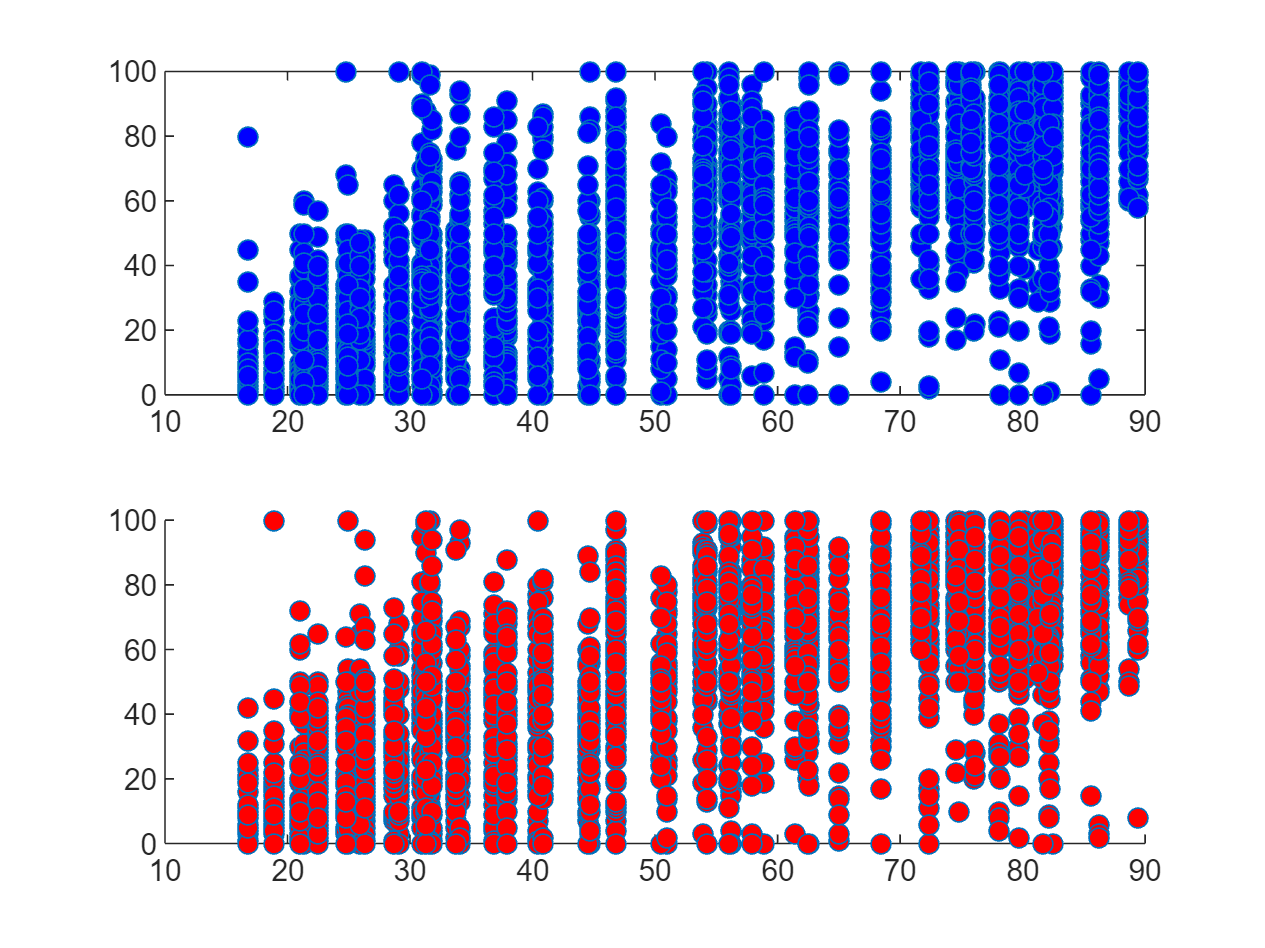


% 
figure
ax1 = subplot(2,1,1);
ax2 = subplot(2,1,2);
plot(ax1, lo.Valence_mean, lo.img_rate, 'o', 'MarkerFaceColor', cuecolor{2}); hold on;
plot(ax2, hi.Valence_mean, hi.img_rate, 'o', 'MarkerFaceColor', cuecolor{1}); 

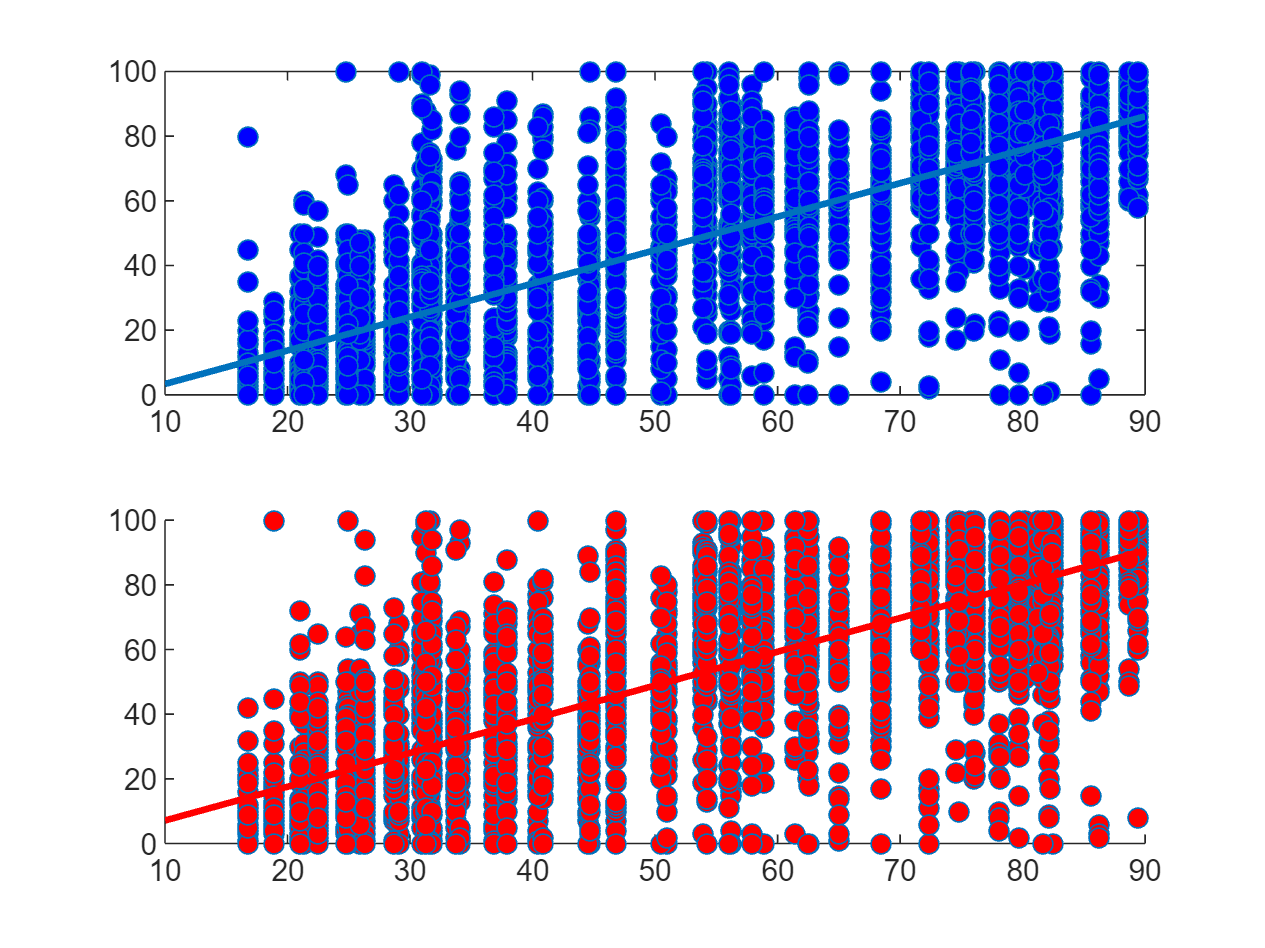


% xconf = [feCI[2,1], feCI[2,2]]

l1 = lsline(ax1);
l1.LineWidth = 2;
l2 = lsline(ax2);
l2.LineWidth = 2;
l2.Color = cuecolor{1};
hold off;


l1

l1 =   Line (lsline) with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [10 90]
              YData: [3.3517 86.1406]
              ZData: [1×0 double]

  Show all properties


l2

l2 =   Line (lsline) with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [10 90]
              YData: [7.1215 90.6244]
              ZData: [1×0 double]

  Show all properties


Plot low vs high as lines w/ variance as shading 

Subtract hi-lo per person to find differences

Create new table that is the generated data

matlab mixed model ypred

Unrecognized function or variable 'testfunction'.


% plot(hi.cue_observed_mean, hi.img_rate, 'o', 'MarkerFaceColor', cuecolor{1}); hold on;
% plot(lo.cue_observed_mean, lo.img_rate, 'o', 'MarkerFaceColor', cuecolor{2})


% val_rating = '1 + cue + normal + (cue|pair) + (cue|sub_id)'
% val_rating = [];
% val_rating = {  'hi/low cue'  'normative rating'   '(cue|pair)'  '(cue|sub_id)' 'img rating'};
% val_rating_2 = { 'pic order' 'hi/low cue' 'cue mean' 'normal'   '(cue|pair)'  '(cue|sub_id)' 'img rating'};
% val_rating_3 = { 'expected rating' 'hi/low cue' 'cue mean' 'normal'   '(cue|pair)'  '(cue|sub_id)' 'img rating'};
% val_rating_4 = {'hi/low cue' 'cue|pair' 'img_rating'};
% 
% test1 = [ master.highcue_indx master.Valence_mean master.Pair master.subj];
% test2 = [master.trial master.highcue_indx master.cue_observed_mean master.Valence_mean master.Pair master.subj];
% test3 = [master.exp_rate master.highcue_indx master.cue_observed_mean master.Valence_mean master.Pair master.subj];
% test4 = [master.highcue_indx master.Pair];
% 
% lm1 = fitlm(test1, master.img_rate, 'VarNames', val_rating;
% 
% lm2 = fitlm(test2, master.img_rate, 'VarNames', val_rating_2;
% lm3 = fitlm(test3, master.img_rate, 'VarNames', val_rating_3);
% lm4 = fitlm(test4, master.img_rate, 'VarNames', val_rating_4);

% gls = fit_gls(1:height(master), master.img_rate, test1)

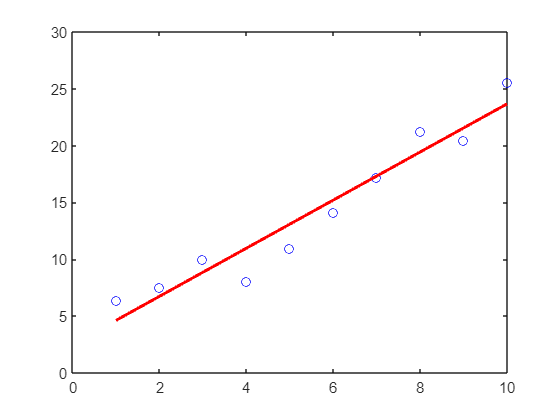

% Generate some random data for x and y coordinates
x = [1:10]';
y = 2*x + 3 + randn(size(x))*2; % Linear model with noise

% Fit a linear model
model = fitlm(x, y);

% Calculate the confidence interval bounds

% Create a figure and plot the data points
figure;
plot(x, y, 'bo');
hold on;

% Plot the linear model
plot(x, predict(model, x), 'r', 'LineWidth', 2);


% Shade the confidence interval
xRegion = [x, fliplr(x)];
yRegion = [predict(model, x), fliplr(ci(:, 1))]; % Lower bound

Error using horzcat
Dimensions of arrays being concatenated are not consistent.

fill(xRegion, yRegion, 'r', 'FaceAlpha', 0.2);
yRegion = [predict(model, x), fliplr(CI(:, 2))]; % Upper bound
fill(xRegion, yRegion, 'r', 'FaceAlpha', 0.2);

hold off;

% Set axis labels and title
xlabel('X');
ylabel('Y');
title('Linear Model with Confidence Interval');
